# Kanika Meeting.....

need to create readme from this, just convert to Lattex and run function

### Analysis completed for meeting with kanika.

we just plotted these analysis, and she took a look. we also worked together to write down all of the significant effects. see the pdf in this folder

- compare temporal evolution of metrics within frequency bands and tasks, i.e., reproduce figures 1 and S1 from the paper for the rest of the tasks. For this, compare all the time points within one frequency band and task (e.g., not just baseline and t1,t2, etc.)

- compare tasks for baseline and first time point only after waking up, within specific frequency bands.

- compare baseline, t1_control, and t1_light for each frequency band and task separately (reproduce figures 2 and S2 from the paper for the rest of the tasks).

[09:29](https://dentlab.slack.com/archives/C03AFPVNCHJ/p1661185767613049)

# Generate Master Data Set

First retreive Master Data Set

DF = dfmaster;


Getting GPSD during PVT Task. . . . . . . . . . . . -done

Getting Network Props during PVT: . . . . . . . . . . . . -done

Getting GPSD during KDT Task. . . . . . . . . . . -done

Getting Network Props during KDT: . . . . . . . . . . . -done

Getting GPSD during MATH Task. . . . . . . . . . . . -done

Getting Network Props during MATH: . . . . . . . . . . . . -done

Getting GPSD during GONOGO Task. . . . . . . . . . . . -done

Getting Network Props during GONOGO: . . . . . . . . . . . . -done


# 1. compare temporal evolution of metrics within frequency bands and tasks, i.e., reproduce figures 1 and S1 from the paper for the rest of the tasks. For this, compare all the time points within one frequency band and task (e.g., not just baseline and t1,t2, etc.) 

### (ready to add to presentation)

Initialize Constants

clearvars -except DF
desired_ntwprop = 'pathl'; % change this to clust or pathl
df_grp = grpAndCleanDf(DF, {'cogtest_order', 'condition', 'run', 'band_ord', 'sbj'}, desired_ntwprop);

All tasks included in this cleaned data frame/n

Visualize

---------------------------------------------


 pathl during PVT TASK # # # # # # # #


## control #######

	### delta ###


		Baseline VS control run 1 * SIGNIFICANT!!!


		control run 1 VS run 2 * SIGNIFICANT (p=0.005 | ni=11, nj=11)
		control run 1 VS run 3 * SIGNIFICANT (p=0.000 | ni=11, nj=11)


	### theta ###


		Baseline VS control run 3 * SIGNIFICANT!!!


		control run 1 VS run 3 * SIGNIFICANT (p=0.034 | ni=11, nj=11)


	### alpha ###
	### beta ###


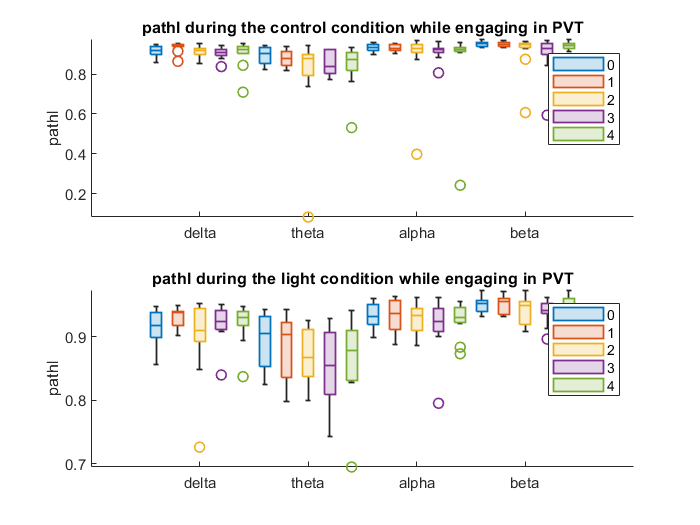

## light #######

	### delta ###


		Baseline VS light run 1 * SIGNIFICANT!!!


	### theta ###
	### alpha ###
	### beta ###


---------------------------------------------


 pathl during Math TASK # # # # # # # #


## control #######

	### delta ###
	### theta ###
	### alpha ###
	### beta ###


		Baseline VS control run 2 * SIGNIFICANT!!!
		Baseline VS control run 3 * SIGNIFICANT!!!
		Baseline VS control run 4 * SIGNIFICANT!!!


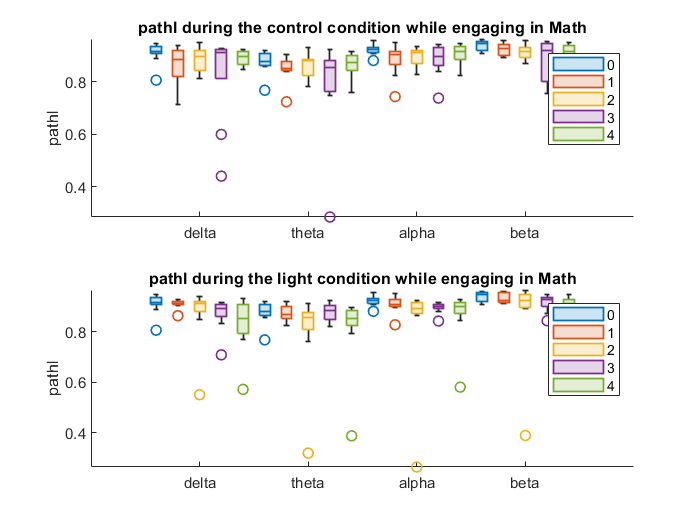

## light #######

	### delta ###


		Baseline VS light run 4 * SIGNIFICANT!!!


		light run 2 VS run 4 * SIGNIFICANT (p=0.038 | ni=9, nj=9)


	### theta ###
	### alpha ###


		Baseline VS light run 3 * SIGNIFICANT!!!


	### beta ###


		Baseline VS light run 3 * SIGNIFICANT!!!


---------------------------------------------


 pathl during GoNogo TASK # # # # # # # #


## control #######

	### delta ###
	### theta ###
	### alpha ###
	### beta ###


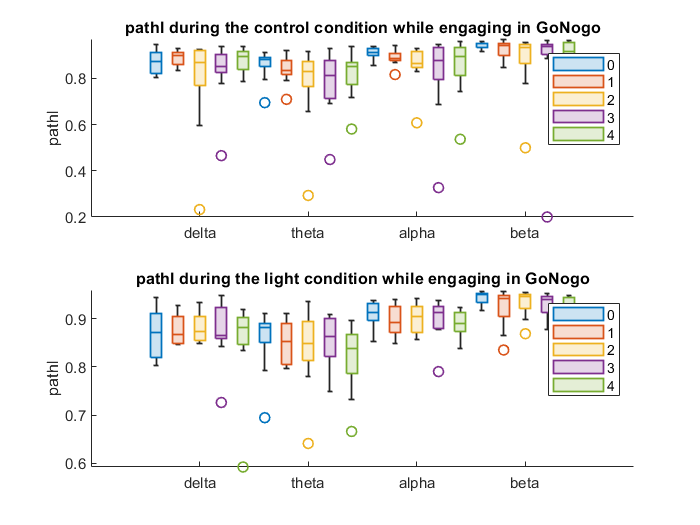

## light #######

	### delta ###
	### theta ###
	### alpha ###
	### beta ###


---------------------------------------------


 pathl during KDT TASK # # # # # # # #


## control #######

	### delta ###
	### theta ###
	### alpha ###
	### beta ###


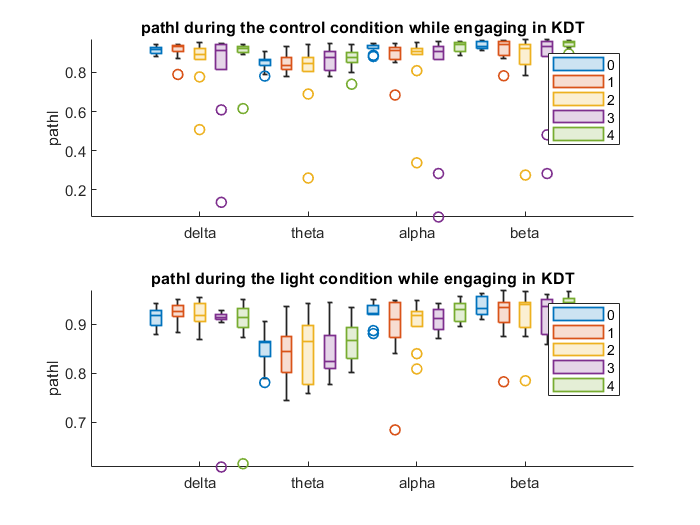

## light #######

	### delta ###
	### theta ###
	### alpha ###
	### beta ###


cogtask_list = unique(df_grp.cogtest_order);
condition_list = {'control', 'light'}; 
band_list       = unique(df_grp.band_ord);
taskpair_list = nchoosek(1:4, 2);

close all
for taskpair_idx = 1:4
    figure;
    cogtask = cogtask_list(taskpair_idx);        
    fprintf('---------------------------------------------\n')
    fprintf(' %s during %s TASK # # # # # # # #\n', desired_ntwprop, cogtask)
    for cond_idx = 1:2
        desired_condition = condition_list{cond_idx};

        df_grp_task = df_grp(df_grp.cogtest_order == cogtask & (df_grp.condition == desired_condition | df_grp.condition == 'baseline'),: );
        
        ax = nexttile;
        boxchart(df_grp_task.band_ord, df_grp_task.mean_Y, 'GroupByColor',df_grp_task.run);
        infostr = sprintf('%s during the %s condition while engaging in %s', desired_ntwprop, desired_condition, cogtask);
        ylabel(desired_ntwprop);

        title(infostr);
        axis tight
        legend
        drawnow;            
        fprintf('## %s #######', desired_condition)        
        for band_idx = 1:4
            band_name = band_list(band_idx);
            fprintf('\t### %s ###\n', band_name) 



            df_bl_rowidx = (df_grp.cogtest_order == cogtask) & (df_grp.condition == 'baseline') & (df_grp.band_ord == band_name) ;
            df_bl       = df_grp(df_bl_rowidx,:); 
            for run_j = 1:4
                df_cntl_r1_rowidx = (df_grp.cogtest_order == cogtask) & (df_grp.condition == desired_condition) & (df_grp.band_ord == band_name) & (df_grp.run == run_j);
                df_cntl_r1 = df_grp(df_cntl_r1_rowidx,:);                                
                [h_bl_vs_cntl,P,CI,STATS] = ttest(df_bl.mean_Y,df_cntl_r1.mean_Y);
                if h_bl_vs_cntl == 1
                    fprintf('\t\tBaseline VS %s run %d * SIGNIFICANT!!!\n', desired_condition, run_j);
%                     fprintf('\t\t%d baseline VS run %d * SIGNIFICANT (p=%.03f | ni=%d, nj=%d)\n', desired_condition, run_i, run_j, P, height(df_run_i), height(df_run_j));
                    
                end
            end
            for runpair_idx = 1:6
                run_i = taskpair_list(runpair_idx,1);
                run_j = taskpair_list(runpair_idx,2); 

                df_run_i_rowidx = (df_grp.cogtest_order == cogtask) & (df_grp.condition == desired_condition) & (df_grp.band_ord == band_name) & (df_grp.run == run_i);
                df_run_i        = df_grp(df_run_i_rowidx,:);

                df_run_j_rowidx = (df_grp.cogtest_order == cogtask) & (df_grp.condition == desired_condition) & (df_grp.band_ord == band_name) & (df_grp.run == run_j);
                df_run_j        = df_grp(df_run_j_rowidx,:);

                [h_bl_vs_cntl,P,CI,STATS] = ttest(df_run_i.mean_Y,df_run_j.mean_Y);
                if h_bl_vs_cntl == 1
                    fprintf('\t\t%s run %d VS run %d * SIGNIFICANT (p=%.03f | ni=%d, nj=%d)\n', desired_condition, run_i, run_j, P, height(df_run_i), height(df_run_j));
                end
            end
        end
    
    end
end

# 2. compare tasks for baseline and first time point only after waking up, within specific frequency bands.

Initialize Constants

clearvars -except DF
desired_ntwprop = 'clust';
df_grp = grpAndCleanDf(DF, {'cogtest_order', 'condition', 'run', 'band_ord', 'sbj'}, desired_ntwprop);

All tasks included in this cleaned data frame/n

Visualize

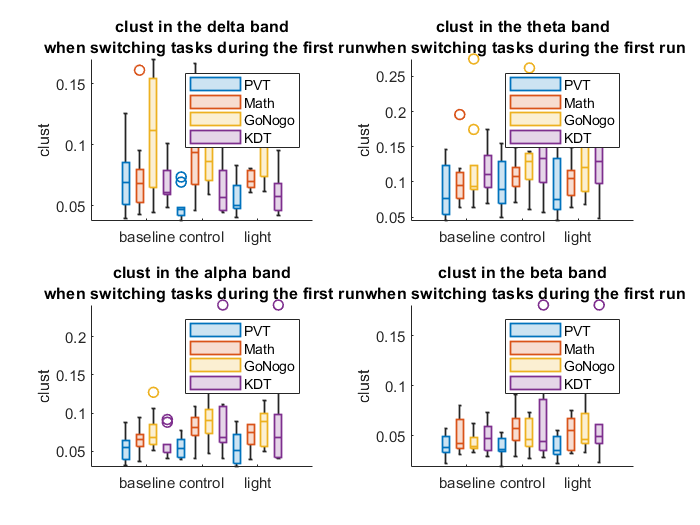

---------------------------------------------


	## delta BAND BASELINE, CONTROL AND LIGHT RUN 1##


---------------------------------------------


	## theta BAND BASELINE, CONTROL AND LIGHT RUN 1##


---------------------------------------------


	## alpha BAND BASELINE, CONTROL AND LIGHT RUN 1##


---------------------------------------------


	## beta BAND BASELINE, CONTROL AND LIGHT RUN 1##


band_list       = unique(df_grp.band_ord);
figure;
for band_idx = 1:4
    band_name = band_list(band_idx);
    fprintf('---------------------------------------------\n')        
    fprintf('\t## %s BAND BASELINE, CONTROL AND LIGHT RUN 1##\n', upper(band_name)); 
    
    df_plot_bl = df_grp(df_grp.band_ord == band_name & df_grp.condition == 'baseline' &  df_grp.run == 0,:); 
    df_plot_r1 = df_grp(df_grp.band_ord == band_name  & df_grp.run == 1,:); 
    df_plot_bl_r1 = [df_plot_bl;df_plot_r1];
    
    ax = nexttile;
    boxchart(df_plot_bl_r1.condition, df_plot_bl_r1.mean_Y, 'GroupByColor',df_plot_bl_r1.cogtest_order);
    infostr = sprintf('%s in the %s band\n when switching tasks during the first run', desired_ntwprop, band_name);
    ylabel(desired_ntwprop);
    axis tight
    title(infostr)
    legend;
    drawnow;           
end

TEST

cogtask_list = unique(df_grp.cogtest_order);
condition_list = {'baseline', 'control', 'light'}; 
band_list       = unique(df_grp.band_ord);
taskpair_list = nchoosek(1:4, 2);

for band_idx = 1:4
    band_name = band_list(band_idx);
    fprintf('---------------------------------------------\n')  
    fprintf('## %s ##\n', band_name);     
    
    for cond_idx = 1:3
        desired_condition = condition_list{cond_idx};
        fprintf('\t%s condition first run \n', upper(desired_condition))
        for taskpair_idx = 1:6
            task_i_idx = taskpair_list(taskpair_idx,1);
            task_j_idx = taskpair_list(taskpair_idx,2);
            task_i = cogtask_list(task_i_idx);
            task_j = cogtask_list(task_j_idx);
            
            % Test
            if strcmp(desired_condition, 'baseline')
                runidx = 0;
            else
                runidx = 1;
            end
            df_i_rowidx = (df_grp.cogtest_order == task_i) & (df_grp.condition == desired_condition) & (df_grp.band_ord == band_name) & (df_grp.run == runidx) ;
            df_j_rowidx = (df_grp.cogtest_order == task_j) & (df_grp.condition == desired_condition) & (df_grp.band_ord == band_name) & (df_grp.run == runidx) ;

            df_i = df_grp(df_i_rowidx,:);
            df_j = df_grp(df_j_rowidx,:);
            
            [h,P,CI,STATS] = ttest2(df_i.mean_Y,df_j.mean_Y);
            if h == 1
                fprintf('\t\t%s vs %s is SIGNIFICANT (p=%.03f|ni=%d|nj=%d )\n', task_i, task_j,P, height(df_i), height(df_j))
            else
                fprintf('\t\t%s vs %s is n.s. (p=%.03f|ni=%d|nj=%d )\n', task_i, task_j,P, height(df_i), height(df_j))
            end
                           

        end
    end
end

---------------------------------------------


## delta ##


	BASELINE condition first run 


		PVT vs Math is n.s. (p=0.769|ni=11|nj=9 )


		PVT vs GoNogo is SIGNIFICANT (p=0.030|ni=11|nj=9 )


		PVT vs KDT is n.s. (p=0.632|ni=11|nj=10 )
		Math vs GoNogo is n.s. (p=0.099|ni=9|nj=9 )
		Math vs KDT is n.s. (p=0.503|ni=9|nj=10 )


		GoNogo vs KDT is SIGNIFICANT (p=0.015|ni=9|nj=10 )


	CONTROL condition first run 


		PVT vs Math is SIGNIFICANT (p=0.001|ni=11|nj=9 )
		PVT vs GoNogo is SIGNIFICANT (p=0.000|ni=11|nj=9 )


		PVT vs KDT is n.s. (p=0.056|ni=11|nj=10 )
		Math vs GoNogo is n.s. (p=0.875|ni=9|nj=9 )


		Math vs KDT is SIGNIFICANT (p=0.044|ni=9|nj=10 )
		GoNogo vs KDT is SIGNIFICANT (p=0.034|ni=9|nj=10 )


	LIGHT condition first run 


		PVT vs Math is SIGNIFICANT (p=0.008|ni=11|nj=9 )
		PVT vs GoNogo is SIGNIFICANT (p=0.000|ni=11|nj=9 )


		PVT vs KDT is n.s. (p=0.509|ni=11|nj=10 )


		Math vs GoNogo is SIGNIFICANT (p=0.012|ni=9|nj=9 )


		Math vs KDT is n.s. (p=0.062|ni=9|nj=10 )


		GoNogo vs KDT is SIGNIFICANT (p=0.001|ni=9|nj=10 )


---------------------------------------------


## theta ##


	BASELINE condition first run 


		PVT vs Math is n.s. (p=0.427|ni=11|nj=9 )
		PVT vs GoNogo is n.s. (p=0.175|ni=11|nj=9 )
		PVT vs KDT is n.s. (p=0.087|ni=11|nj=10 )
		Math vs GoNogo is n.s. (p=0.473|ni=9|nj=9 )
		Math vs KDT is n.s. (p=0.416|ni=9|nj=10 )
		GoNogo vs KDT is n.s. (p=0.852|ni=9|nj=10 )


	CONTROL condition first run 


		PVT vs Math is n.s. (p=0.582|ni=11|nj=9 )
		PVT vs GoNogo is n.s. (p=0.153|ni=11|nj=9 )
		PVT vs KDT is n.s. (p=0.168|ni=11|nj=10 )
		Math vs GoNogo is n.s. (p=0.274|ni=9|nj=9 )
		Math vs KDT is n.s. (p=0.313|ni=9|nj=10 )
		GoNogo vs KDT is n.s. (p=0.712|ni=9|nj=10 )


	LIGHT condition first run 


		PVT vs Math is n.s. (p=0.654|ni=11|nj=9 )
		PVT vs GoNogo is n.s. (p=0.176|ni=11|nj=9 )
		PVT vs KDT is n.s. (p=0.111|ni=11|nj=10 )
		Math vs GoNogo is n.s. (p=0.245|ni=9|nj=9 )
		Math vs KDT is n.s. (p=0.170|ni=9|nj=10 )
		GoNogo vs KDT is n.s. (p=0.717|ni=9|nj=10 )


---------------------------------------------


## alpha ##


	BASELINE condition first run 


		PVT vs Math is n.s. (p=0.241|ni=11|nj=9 )


		PVT vs GoNogo is SIGNIFICANT (p=0.043|ni=11|nj=9 )


		PVT vs KDT is n.s. (p=0.500|ni=11|nj=10 )
		Math vs GoNogo is n.s. (p=0.264|ni=9|nj=9 )
		Math vs KDT is n.s. (p=0.601|ni=9|nj=10 )
		GoNogo vs KDT is n.s. (p=0.127|ni=9|nj=10 )


	CONTROL condition first run 


		PVT vs Math is SIGNIFICANT (p=0.010|ni=11|nj=9 )
		PVT vs GoNogo is SIGNIFICANT (p=0.001|ni=11|nj=9 )


		PVT vs KDT is n.s. (p=0.067|ni=11|nj=10 )
		Math vs GoNogo is n.s. (p=0.718|ni=9|nj=9 )
		Math vs KDT is n.s. (p=0.788|ni=9|nj=10 )
		GoNogo vs KDT is n.s. (p=0.955|ni=9|nj=10 )


	LIGHT condition first run 


		PVT vs Math is SIGNIFICANT (p=0.049|ni=11|nj=9 )
		PVT vs GoNogo is SIGNIFICANT (p=0.019|ni=11|nj=9 )


		PVT vs KDT is n.s. (p=0.096|ni=11|nj=10 )
		Math vs GoNogo is n.s. (p=0.780|ni=9|nj=9 )
		Math vs KDT is n.s. (p=0.608|ni=9|nj=10 )
		GoNogo vs KDT is n.s. (p=0.715|ni=9|nj=10 )


---------------------------------------------


## beta ##


	BASELINE condition first run 


		PVT vs Math is n.s. (p=0.151|ni=11|nj=9 )
		PVT vs GoNogo is n.s. (p=0.413|ni=11|nj=9 )
		PVT vs KDT is n.s. (p=0.103|ni=11|nj=10 )
		Math vs GoNogo is n.s. (p=0.430|ni=9|nj=9 )
		Math vs KDT is n.s. (p=0.996|ni=9|nj=10 )
		GoNogo vs KDT is n.s. (p=0.364|ni=9|nj=10 )


	CONTROL condition first run 


		PVT vs Math is SIGNIFICANT (p=0.011|ni=11|nj=9 )


		PVT vs GoNogo is n.s. (p=0.086|ni=11|nj=9 )
		PVT vs KDT is n.s. (p=0.077|ni=11|nj=10 )
		Math vs GoNogo is n.s. (p=0.813|ni=9|nj=9 )
		Math vs KDT is n.s. (p=0.605|ni=9|nj=10 )
		GoNogo vs KDT is n.s. (p=0.530|ni=9|nj=10 )


	LIGHT condition first run 


		PVT vs Math is n.s. (p=0.058|ni=11|nj=9 )
		PVT vs GoNogo is n.s. (p=0.053|ni=11|nj=9 )
		PVT vs KDT is n.s. (p=0.095|ni=11|nj=10 )
		Math vs GoNogo is n.s. (p=0.480|ni=9|nj=9 )
		Math vs KDT is n.s. (p=0.469|ni=9|nj=10 )
		GoNogo vs KDT is n.s. (p=0.871|ni=9|nj=10 )


# 3. compare baseline, t1_control, and t1_light for each frequency band and task separately (reproduce figures 2 and S2 from the paper for the rest of the tasks).

### Ready for presenting

Initialize Constants

clearvars -except DF
desired_ntwprop = 'pathl';
df_grp = grpAndCleanDf(DF, {'cogtest_order', 'condition', 'run', 'band_ord', 'sbj'}, desired_ntwprop);

VISUALIZE

cogtask_list = unique(df_grp.cogtest_order);
close all

figure;    
for taskpair_idx = 1:4
    cogtask = cogtask_list(taskpair_idx);   
    df_plot_bl = df_grp(df_grp.cogtest_order == cogtask & df_grp.condition == 'baseline',:); 
    df_plot_r1 = df_grp(df_grp.cogtest_order == cogtask & df_grp.run == 1,:); 
    df_plot_bl_r1 = [df_plot_bl;df_plot_r1];
    
    
    ax = nexttile;
    boxchart(df_plot_bl_r1.band_ord, df_plot_bl_r1.mean_Y, 'GroupByColor',df_plot_bl_r1.condition);
    infostr = sprintf('%s during run 1\n while engaging in %s', desired_ntwprop, cogtask);
    ylabel(desired_ntwprop);
    title(infostr);
    axis tight
    drawnow;           
    legend
    legend({'baseline','Control T1', 'Light T1'});
drawnow    

end

Test

cogtask_list = unique(df_grp.cogtest_order);
condition_list = {'control', 'light'}; 
band_list       = unique(df_grp.band_ord);
taskpair_list = nchoosek(1:4, 2);

for taskpair_idx = 1:4
    cogtask = cogtask_list(taskpair_idx); 
    fprintf('---------------------------------------------\n')        
    fprintf('## %s %s ##', cogtask, desired_ntwprop)   
    for band_idx = 1:4
        band_name = band_list(band_idx);
        fprintf('\t### %s ###\n', band_name) 

        % Test
        df_bl_rowidx = (df_grp.cogtest_order == cogtask) & (df_grp.condition == 'baseline') & (df_grp.band_ord == band_name) ;
        df_bl           = df_grp(df_bl_rowidx,:); 

        df_cntl_r1_rowidx = (df_grp.cogtest_order == cogtask) & (df_grp.condition == 'control') & (df_grp.band_ord == band_name) & (df_grp.run == 1);
        df_cntl_r1 = df_grp(df_cntl_r1_rowidx,:); 

        df_light_r1_rowidx = (df_grp.cogtest_order == cogtask) & (df_grp.condition == 'light') & (df_grp.band_ord == band_name) & (df_grp.run == 1);
        df_light_r1 = df_grp(df_light_r1_rowidx,:);             

        [h_bl_vs_cntl, p_cntl] = ttest(df_bl.mean_Y,df_cntl_r1.mean_Y);
        [h_bl_vs_light,p_light] = ttest(df_bl.mean_Y,df_light_r1.mean_Y);
        [h_cntl_vs_light,p_cntl_vs_light] = ttest(df_cntl_r1.mean_Y,df_light_r1.mean_Y);
        

        if h_bl_vs_cntl == 1
            fprintf('\t\t - bl VS control run 1 * SIGNIFICANT (p=%.03f |Nbl=%d , Ncntl = %d)\n',p_cntl, height(df_bl), height(df_cntl_r1));            
        end

        if h_bl_vs_light == 1
            fprintf('\t\t - bl VS Light run 1 * SIGNIFICANT (p=%.03f |Nbl=%d , Nlight = %d)\n',p_light, height(df_bl), height(df_light_r1));            
        end

        if h_cntl_vs_light == 1
            fprintf('\t\t - Control run1 VS Light run 1 * SIGNIFICANT (p=%.03f |Ncntl=%d , Nlight = %d)\n',p_cntl_vs_light, height(p_cntl_vs_light), height(df_light_r1));            
        end        


    end


end

# Functions

### Extract subset of master data frame and average accross channels, bands and subjects

function df_grouped = grpAndCleanDf(DF, groupingvars, desired_ntwprop, opts)

    % this function is important 
    %   averages accross/groups by the desired variables, but it does so
    %   independently for each task. The reason for this is, because
    %   different tasks have different subjects, so we want to first toss
    %   the data from the bad subjects of each task, and then run the
    %   average. Ideally, this should be done when generating the master
    %   data frame but, i havent had time to do this
    %
    %   furthermo it forces the user to define the network property that is
    %   desired. this prevents accidentally averaging accross network
    %   properties because the master data frame contains all the network
    %   properties
    %
    %   an added benefit is that it removes un used categories 
    arguments
        DF
        groupingvars
        desired_ntwprop 
        opts.removekdt = false;
    end
    extdf = @(cogtask, ntw, sbj) DF( ((DF.cogtest_order == cogtask)) & any((DF.ntwprop == ntw),2)  &  ismember(DF.sbj, sbj),:);
    df_pvt      = extdf('PVT', desired_ntwprop, goodsbj('PVT'));
    df_math     = extdf('Math', desired_ntwprop, goodsbj('Math'));
    df_gonogo   = extdf('GoNogo', desired_ntwprop, goodsbj('GoNogo'));
    df_kdt      = extdf('KDT', desired_ntwprop, goodsbj('KDT'));
    
    if opts.removekdt
        df = [df_pvt;df_math;df_gonogo]; 
        fprintf('KDT removed from this data frame/n')        
    else
        df = [df_pvt;df_math;df_gonogo;df_kdt];
        fprintf('All tasks included in this cleaned data frame/n')
    end
 

    df_grouped = varfun(@mean, df, "InputVariables","Y","GroupingVariables",groupingvars);
    df_grouped = dfrmcats(df_grouped);

end

### Create new table with complex network variable

function df_cpx = makecomplexdf(DF, desired_cogtask, desired_condition)
    DF.run      = categorical(DF.run,[0, 1, 2, 3, 4], 'Ordinal',true);
    DF.band_ord = categorical(DF.band,{'delta', 'theta', 'alpha', 'beta'}, 'Ordinal',true);
    
    DF.band_level = nan(height(DF),1);
    DF.band_level(DF.band == 'delta')   = 1;
    DF.band_level(DF.band == 'theta')   = 2;
    DF.band_level(DF.band == 'alpha')   = 3;
    DF.band_level(DF.band == 'beta')    = 4;
    
    % To average a variable accross a group, I like this function better, makes
    % more sense to me % WARNING THIS MAY LEAD TO SOME ISSUES IN AVERAGING.
    % MAKE SURE THE NEW DATA FRAME DOES NOT HAVE THE VARIABLE YOU WISH TO
    % AVERAGING. THIS IS NOT A PROBLE IN THIS FUNCTION BECAUSE WE ARE ONLY
    % AVERAGING ACROSS CHANNELS, BUT WHEN AVERAGING ACCROSS OTHER VARIABLES
    % - SUCH AS RUNS AND RUN UNIQUE - WHICH ARE DIFFERENT VERSIONS OF THE
    % SAME VARIABLES, THE AVERAGING MAY NOT OCCUR
    groupingvars    = @(df, inputvar, averageaccross) df.Properties.VariableNames ( ~ ismember(df.Properties.VariableNames, [inputvar, averageaccross]) );
    getgroupeddf    = @(df, inputvar, averageaccross) varfun(@mean, df, "InputVariables",inputvar,"GroupingVariables",groupingvars(df, inputvar,averageaccross ));
    commonrows      = @(cogtask, condition) (DF.cogtest == cogtask) & ismember(DF.sbj, goodsbj(cogtask)) & (any((DF.condition == condition),2));
    
    % Get the data set with the clustering variable 
    df_clust    = DF(commonrows(desired_cogtask, desired_condition)  & DF.ntwprop == 'clust',:);
    df_clust    = getgroupeddf(df_clust, "Y", "chan");
    df_clust    =  renamevars(df_clust, 'mean_Y', 'Y');
    
    % Get the data set with the path length variable 
    df_pathl    = DF(commonrows(desired_cogtask, desired_condition)  & DF.ntwprop == 'pathl',:);
    df_pathl    = getgroupeddf(df_pathl, "Y", "chan");
    df_pathl    =  renamevars(df_pathl, 'mean_Y', 'Y');
    
    % Validate that the data sets have all other variables in common
    var_names = DF.Properties.VariableNames;
    for i = 1:numel(var_names)
        varname = var_names{i};
        switch varname
            case {'Y', 'ntwprop', 'chan'}

            otherwise
                samevals         = all(df_clust.(varname) == df_pathl.(varname));
                if not(samevals)
                    error('LUIS: somethin up')       
                end
        end
    end

    df_cpx                  = table;
    df_cpx.clust            = df_clust.Y;
    df_cpx.pathl            = (df_pathl.Y);
    df_cpx.pathl_imag       = (df_pathl.Y)*1i;
    df_cpx.cpx              = df_cpx.clust + df_cpx.pathl_imag;
    df_cpx.angle            = angle(df_cpx.cpx);
    df_cpx.mag              = abs(df_cpx.cpx);

    df_cpx.condition        = df_clust.condition;
    df_cpx.band             = df_clust.band;    
    df_cpx.band_ord         = df_clust.band_ord;    
    
    df_cpx.run              = df_clust.run;
    df_cpx.sbj              = df_clust.sbj;
    
    df_cpx =  dfrmcats(df_cpx);

end



### ---

## Back burner: hings To Do

Use clustered regression techniques as discussed with jodi or mixed effects model as discussed with nasa

- initial methods, for samples at 2 time points:

-  - Clustered robust standard error regression R package to use: huber white standard  regrsion package

- More complex method, for more that 2 time points:

- - longitudinal mixed models

 New plots of new SFN claims

using wpli matrix, create a graph structure!!!! 

Assess visually using using matlabs graph structure and  wpli matrix\

recreate figure 3 with new data frame and topoplot functionality